radarReference;

fixedPoint = true;
if(fixedPoint)
    fpDataType = fixdt(1,24,8);
    fpDataType2 = fixdt(1,16,12);
else %else floating point
    fpDataType = "double"
end

%% Simulate model
simTime = length(txSig) + windowLen-nOverlap;
slout = sim('radarSim4');

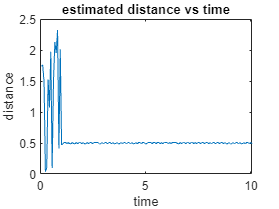


Maximum error for matlab vs simulink distance out of 156 values
absolute : 1.914104e+00
percentage : 8.236294e+01
mse : 1.142395e-01

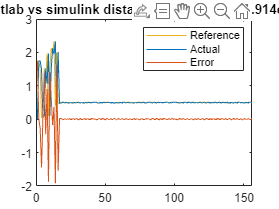



distSL = getLogged(slout, "dist");
distSL = distSL(windowLen-nOverlap + 1 : end); %remove dead time at start
distSL = downsample(distSL, windowLen-nOverlap);

%remove last sample of matlab and simulink because they disagree for some
distSL = distSL(1:end-1);
dist = dist(1:end-1);

%compare distance data to matlab
compareData(dist, distSL, {3 1 1}, "matlab vs simulink distance");